## **Question 1**

- Consider the the Lorenz-96 model (4) with the setting used in Project 1. The data assimilation problem is posed over the interval [0, T], starting with initial background states from N (x b 0 , B0). Observations are available at times ti = i ∆t, i = 0, . . . , N, tN = T. Use your synthetic observations, observation error covariance, and observation operator from Project 1.

**The code below is taken from my Project 1 implementation.**

**1.1)**

- Implement the Lorenz-96 model (1) and solve it using a Matlab ode solver (ode45 or one integrator selected from MATLODE).

- Start with an initial condition where the states are drawn from a random distribution (e.g., x0 ∼N (0, 16)), then integrate for 5 time units. Save the result. This is our x[-1]true.

- Propagate for ∆t time units, and save. This is our reference state x[0]true.

- (You can use ∆t = 0.1.)

clear;
close all;
clc;

% Setting seed for reproducibility
rng(381996)

% Importing Lorenz96 model
m = otp.lorenz96.presets.Canonical;

% Model configurations
n_states = 40;
n_obs = 20;
x0 = normrnd(0,sqrt(16),[n_states,1]); % Inital condition of y0 drawn from N(0,16)
dt = 0.1; % time step unit

% Solving for for 5 time units (0.5) using inital conditions above
[~, x] = ode45(m.RHS.F, [0 dt*5], x0); % This is x[-1]true/reference state.
x_true_n1 = x(end,:).'; % Extracting states at final timestep

% Propogating for dt
[~, x] = ode45(m.RHS.F, [dt*5, dt*6], x_true_n1); % This is x[-1]true/reference state
x_true = x(end,:).'; % Extracting states at final timestep

**1.2)**

- Compute Nens normal random perturbations εbi ∼ N (0, σ2 INstate ) with σ = 0.2.

- Add to x[-1]true, and integrate the system starting from the perturbed initial conditions for ∆t time units.

- Save the resulting Nens states x. The members of this ensemble represent our set of background states Xb[0] .

n_ens = 500;
sigma = 0.2;

% create ensemble members from perturbations of x_true
eps = normrnd(0,sigma,[n_states,n_ens]); % Perturbations (note normrnd(mu,sigma))
x_perturbed_n1 = x_true_n1 + eps;  % Adding to x_true[-1]

% init storage for ensemble (background state)
X_b_ens = zeros(n_states, n_ens);

% intergate system for one time unit for each ensemble member, store result
for i = 1:n_ens
    [~, x_ens] = ode45(m.RHS.F, [5*dt 6*dt], x_perturbed_n1(:, i));
    X_b_ens(:, i) = x_ens(end, :);
end

**1.3)**

- Using a large number of ensemble members compute the ensemble covariance Pb0.

- Check its condition number. If it is large build a modified background covariance that leads to a reasonably small condition number of the resulting covariance.

- This is our B0.

% A problem is called well-conditioned, if its condition number is small,
% i.e., in the order of 10, 100 or 1000
% and ill-conditioned if it is large: in the order of 10^6 - 10^10, and larger.
% https://cms.uni-konstanz.de/fileadmin/archive/informatik-saupe/fileadmin/informatik/ag-saupe/Webpages/lehre/na_08/Lab1/5_CondStab/html/CondStab.html

% Inbuilt covariance method
B0 = cov(X_b_ens.');
% Manual covariance check
X_ens_mean = mean(X_b_ens, 2);
X_delta = X_b_ens - X_ens_mean;
B0_manual = (1/(n_ens-1)).*(X_delta*X_delta.');

cond(B0), cond(B0_manual)

ans = 2.9553

ans = 2.9553

% Not needed as condition number is small
alpha = 0.1;
B0_downscale = (1-alpha)*B0 + alpha*eye(n_states);
cond(B0_downscale)

ans = 1.3145

B0 = B0_downscale

B0 =     0.1350   -0.0015   -0.0000   -0.0007   -0.0009   -0.0003   -0.0013   -0.0003    0.0013    0.0001    0.0003    0.0004    0.0003   -0.0020   -0.0022   -0.0007    0.0018   -0.0013   -0.0034    0.0008   -0.0006    0.0007    0.0003   -0.0005    0.0010    0.0021    0.0004   -0.0004    0.0001   -0.0001   -0.0019   -0.0012   -0.0010   -0.0010   -0.0009   -0.0015   -0.0011   -0.0025   -0.0004   -0.0016
   -0.0015    0.1329    0.0014   -0.0022   -0.0004    0.0030   -0.0006    0.0002   -0.0016   -0.0015    0.0032    0.0010    0.0004   -0.0003   -0.0004    0.0012   -0.0006   -0.0009    0.0019   -0.0018   -0.0011    0.0015    0.0019    0.0006    0.0006   -0.0003   -0.0032    0.0000    0.0007    0.0007    0.0012    0.0004   -0.0007    0.0005    0.0001    0.0031   -0.0026   -0.0021    0.0012   -0.0003
   -0.0000    0.0014    0.1375    0.0051   -0.0025    0.0007   -0.0011    0.0003    0.0010    0.0005   -0.0001   -0.0019    0.0004    0.0006   -0.0010    0.0006    0.0007    0.0001   -0.0007   

**1.4) **

- Obtain x0b by selecting one state with the smallest deviation from xtrue

[M,I] = min(sum(abs(X_b_ens - x_true(end,:).')));
x0b = X_b_ens(:, I);

% Hack work around as x0b was very far from the truth and all analysis
% probabilties were zero.
%x0b = x_true

**1.5)**

- Run the reference trajectory starting from x_true[0] over the interval [0, T].

- Save the solution every ∆t time units.

- At each ti = i ∆t generate N_ens synthetic observations by adding to the reference solution H*xi normal random noise drawn from N (0, R), R = r^2 I N_obs, with r = 0.025.

T = 10;
time_steps = 0:dt:T;
x_start = x_true; % Storing inital x_true[0]

X_ref = zeros(n_states, length(time_steps));
X_ref(:, 1) = x_start;

% Run forward model and save results at each timestep
for t_id = 1:(length(time_steps)-1)
    [~, x] = ode45(m.RHS.F, [time_steps(t_id) time_steps(t_id)+dt], x_start);
    X_ref(:, t_id+1) = x(end,:);
    x_start = x(end,:).'; % For next iterations, use starting conditions based on prior state

end


% Apply observation operator and add random noise to reference trajectory

% Generating observation operator (observing every odd state)
A = eye(n_obs);
M = 1;
k = 1;
N = size(A);
H = reshape([reshape(A,M,[]);zeros(k,N(1)/M*N(2))],[],N(2)).';

% Applying observation vector to reference trajectory
% H * Reference -> Observations, Clone Observatations + noise -> ensemble 
X_obvs = H * X_ref;
X_obvs_ens = repmat(X_obvs, 1,1, n_ens);

% Generating and applying observation noise (for each ensemble member)
obvs_sigma = 0.025;
R = obvs_sigma.^2 * eye(n_obs);
obvs_noise = normrnd(0,obvs_sigma,size(X_obvs_ens));  % (note normrnd(mu,sigma))
X_obvs_ens = X_obvs_ens + obvs_noise;

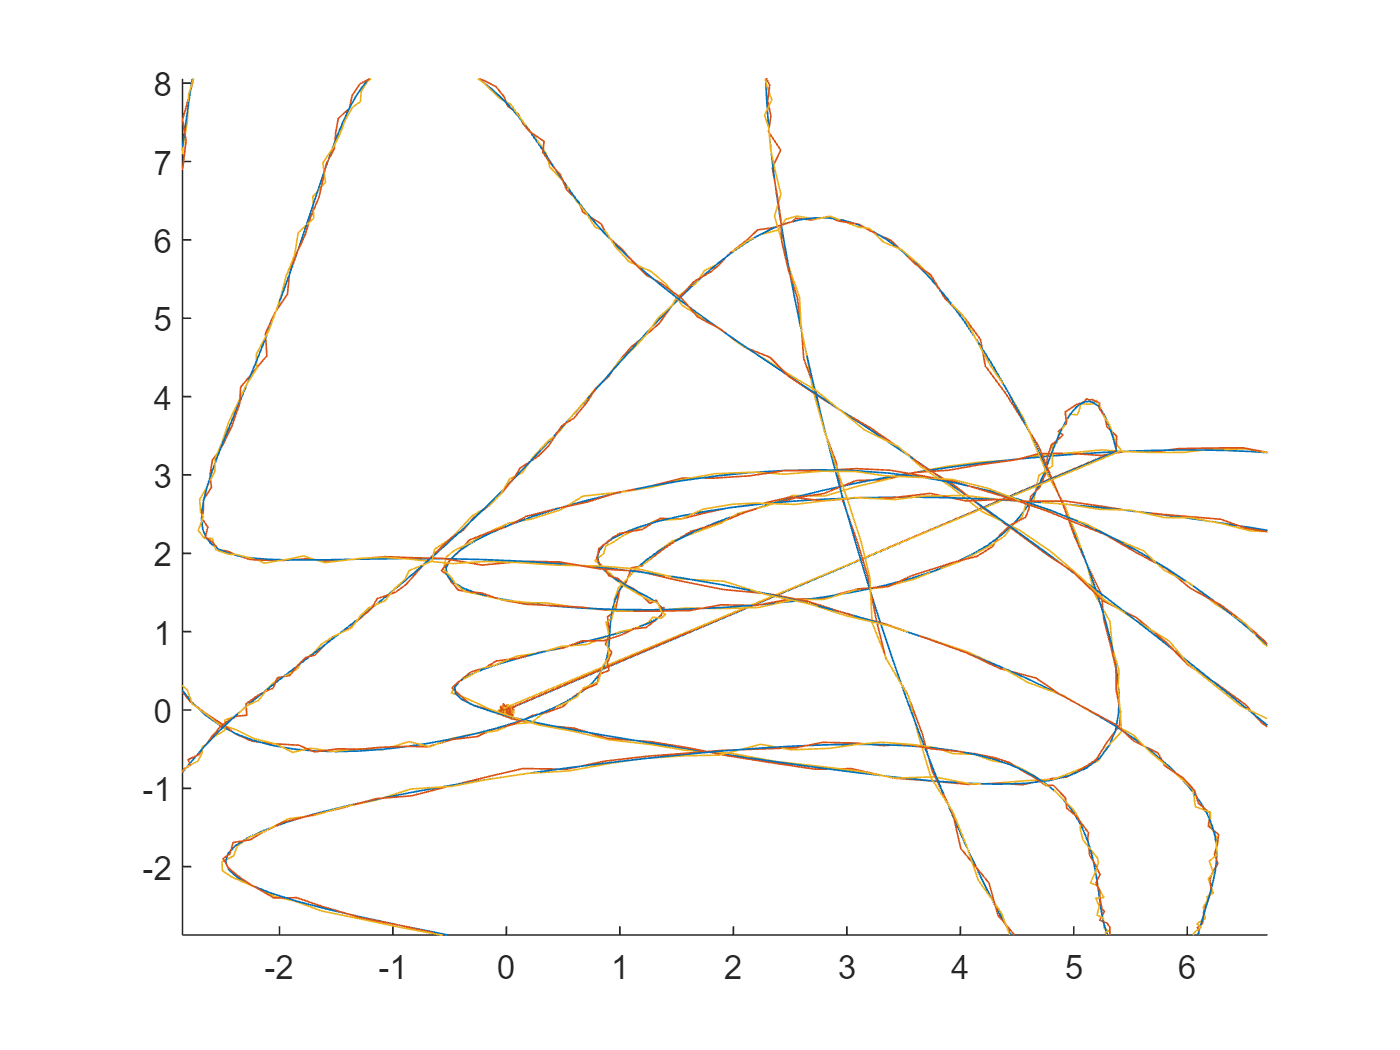

% Plotting sample reference and perturbed states (for 2 random ensemble members)
% Note that state number 1,3,5 in reference -> 1,2,3 due to H
clf
hold on
plot3(X_ref(1, :), X_ref(3, :), X_ref(5, :));
plot3(X_obvs_ens(1, :, 1), X_obvs_ens(2, :, 1), X_obvs_ens(3, :, 1));
plot3(X_obvs_ens(1, :, 2), X_obvs_ens(2, :, 2), X_obvs_ens(3, :, 2));
hold off

## **Question 2**

**2.1)**

- Consider the data assimilation problem posed over the interval [0, T], starting with initial background states from N (xb[0] , B0).

- Observations are available at times ti = i ∆t, i = 0, . . . , N, tN = T. Use your synthetic observations, observation error covariance, and observation operator from above.

% Unclear if these need to be resampled from this distribution or use the previously generated ensemble
X_ens_b = mvnrnd(x0b,B0,n_ens).'; 

**2.2)**

- Solve the data assimilation problem using the standard sequential importance with resampling (SIR) particle filter. 

- Resample when the effective number of particles decreases below a fraction of the total number, Neff ens ≤ α Nens, with 0 < α < 1 a tuning parameter under your control.

w =     0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020


X_prediction =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    

n_eff = 477.2861

n_eff = 421.2112

n_eff = 320.9566

n_eff = 183.3235

n_eff = 69.3703

n_eff = 24.0494

Reampling!


n_eff = 368.2522

n_eff = 179.6953

n_eff = 96.0039

n_eff = 90.3524

n_eff = 22.3715

Reampling!


n_eff = 391.0256

n_eff = 290.1828

n_eff = 364.2690

n_eff = 26.9560

Reampling!


n_eff = 432.4012

n_eff = 432.2386

n_eff = 427.1169

n_eff = 422.1361

n_eff = 419.7040

n_eff = 416.6751

n_eff = 410.8934

n_eff = 400.7752

n_eff = 392.4295

n_eff = 373.8249

n_eff = 342.7715

n_eff = 344.7132

n_eff = 327.3953

n_eff = 319.6467

n_eff = 242.4738

n_eff = 225.5775

n_eff = 207.5542

n_eff = 132.8053

n_eff = 162.9736

n_eff = 167.6008

n_eff = 115.1141

n_eff = 91.3271

n_eff = 105.7580

n_eff = 94.0035

n_eff = 75.6705

n_eff = 59.1940

n_eff = 25.0520

Reampling!


n_eff = 20.1656

Reampling!


n_eff = 282.5982

n_eff = 168.0531

n_eff = 128.2361

n_eff = 103.8099

n_eff = 80.2587

n_eff = 74.5627

n_eff = 64.5805

n_eff = 70.0566

n_eff = 62.3849

n_eff = 55.6735

n_eff = 6.1291

Reampling!


n_eff = 481.2237

n_eff = 460.9006

n_eff = 5.0137

Reampling!


n_eff = 451.8216

n_eff = 229.9565

n_eff = 58.8690

n_eff = 368.6635

n_eff = 315.2035

n_eff = 318.0197

n_eff = 48.4698

Reampling!


n_eff = 429.8065

n_eff = 231.8371

n_eff = 107.2676

n_eff = 87.2393

n_eff = 108.9419

n_eff = 59.7160

n_eff = 32.3964

Reampling!


n_eff = 417.9038

n_eff = 63.2916

n_eff = 26.8454

Reampling!


n_eff = 446.1069

n_eff = 388.5488

n_eff = 252.0588

n_eff = 122.3654

n_eff = 115.2428

n_eff = 150.9356

n_eff = 104.8748

n_eff = 74.2955

n_eff = 69.8958

n_eff = 65.2854

n_eff = 58.1937

n_eff = 49.7348

Reampling!


n_eff = 433.8024

n_eff = 400.8006

n_eff = 371.5926

n_eff = 296.3342

n_eff = 233.1274

n_eff = 199.8296

n_eff = 155.6795

n_eff = 121.9212

n_eff = 96.1411

n_eff = 81.9144

n_eff = 44.9856

Reampling!


n_eff = 421.6317

n_eff = 391.4913

n_eff = 354.6807

n_eff = 140.5754

EnKF run complete


rmse_particle =     0.2207    0.2337    0.2676    0.2981    0.2789    0.2353    0.2807    0.3234    0.3299    0.3659    0.3644    0.5152    0.6961    0.9553    1.2827    1.0205    1.3359    1.4938    1.4445    1.4436    1.5152    1.6948    1.9191    2.0635    2.1783    2.6974    3.1364    3.3865    3.7711    3.9696    4.0829    4.0468    4.0572    4.1158    4.0126    4.2894    4.6847    4.8155    4.7755    4.7726    4.9266    4.9958    5.0575    5.1589    5.0086    4.5786    4.3787    4.6269    4.9140    4.8895


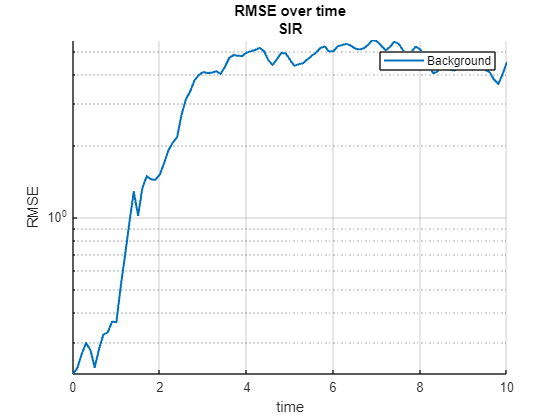

test = donald_SIR(m, X_ens_b, X_obvs_ens, X_ref, H, time_steps, n_states, n_ens, 1);

**2.3)**

- Solve the data assimilation problem using a square root filter (EnSRF), e.g., ETKF.

- You will need to implement the filter, run it, and assess the quality of the results.

[X_ens_array] = donald_ETKF(m, X_ens_b, X_obvs, X_obvs_ens, X_ref, H, time_steps, n_states, n_ens, covar_localization, covar_inflation, plot);

Unrecognized function or variable 'covar_localization'.

**2.4)**

For each case plot: 

- The time evolution of the error in the analysis ensemble mean, compared to the reference trajectory.

- The rank histogram for one of the observations.

% Done above

**2.5)**

- Apply covariance localization. Use a Gaspari-Cohn function with a decorrelation parameter L = 5.

- Repeat the EnKF and ETKF numerical experiments and compare the results against the analysis obtained without localization.

% Updated filter configurations (covar localization)
covar_localization = 1; % True
covar_inflation = 0; % False

[X_ens_array] = donald_EnKF(m, X_ens_b, X_obvs_ens,X_ref, H, time_steps, R, n_states, n_ens, covar_localization, covar_inflation, L, alpha, plot);
[X_ens_array] = donald_LETKF(m, X_ens_b,X_obvs, X_obvs_ens, X_ref, H, time_steps, n_states, n_ens, covar_inflation, L, alpha, plot);

**2.6)**

- In addition to localization, apply multiplicative covariance inflation with a parameter α = 1.02.

-  Again, repeat the EnKF and ETKF numerical experiments, and compare the results against the analysis obtained before. 

% Filter configurations (localization and covar inflation)
covar_localization = 1; % True
covar_inflation = 1; % False


[X_ens_array] = donald_EnKF(m, X_ens_b, X_obvs_ens,X_ref, H, time_steps, R, n_states, n_ens, covar_localization, covar_inflation, L, alpha, plot);
covar_localization = 0; % Should be True - but localization for ETKF not implemented yet!

[X_ens_array] = donald_LETKF(m, X_ens_b, X_obvs, X_obvs_ens, X_ref, H, time_steps, n_states, n_ens, covar_inflation, L, alpha, plot);